# chi_square_usv_example.m

Chi-square (χ²) test example for neuroscience-style categorical data

Goal: Test whether two categorical variables are associated.

Example question: "Is USV type (22 kHz vs 50 kHz) associated with learning phase (Early vs Late)?"

Data type: COUNTS (categorical outcomes), arranged as a contingency table.

What χ² (chi-square test of independence) does: Compares the OBSERVED counts in each cell to the EXPECTED counts you would get if the two variables were independent (unrelated).

Null hypothesis (H0): USV type is independent of learning phase (no association).

Alternative hypothesis (H1): USV type and learning phase are associated (not independent).

Requirements / assumptions (practical): - Counts are frequencies of independent observations. - Expected counts should generally be >= 5 in each cell (rule of thumb). If expected counts are small, consider Fisher's exact test instead.

Output: - chi2stat: χ² test statistic - dof: degrees of freedom - p: p-value (probability of observing a χ² this large or larger under H0) - expected: expected cell counts under independence - effect size (optional): Cramér's V

clear; clc;

## 1) Enter the observed contingency table (counts)

Rows: USV type (22 kHz, 50 kHz) Columns: Learning phase (Early, Late)

observed = [30 10;
            20 40];

rowLabels = ["22 kHz", "50 kHz"];
colLabels = ["Early", "Late"];

fprintf('Observed counts (O):\n');

Observed counts (O):


disp(array2table(observed, 'RowNames', cellstr(rowLabels), 'VariableNames', cellstr(colLabels)));

              Early    Late
              _____    ____

    22 kHz     30       10 
    50 kHz     20       40 



## 2) Compute totals needed for expected counts

Row totals, column totals, and the grand total:

rowTotals   = sum(observed, 2);   % sum across columns
colTotals   = sum(observed, 1);   % sum across rows
grandTotal  = sum(observed, 'all');

fprintf('\nRow totals:\n'); disp(rowTotals);


Row totals:
    40
    60



fprintf('Column totals:\n'); disp(colTotals);

Column totals:
    50    50



fprintf('Grand total:\n'); disp(grandTotal);

Grand total:
   100



## 3) Compute expected counts (E) under independence

Under independence: Expected(i,j) = (RowTotal(i) * ColTotal(j)) / GrandTotal

In matrix form this is: expected = (rowTotals * colTotals) / grandTotal

expected = (rowTotals * colTotals) / grandTotal;

fprintf('\nExpected counts under H0 (E):\n');


Expected counts under H0 (E):


disp(array2table(expected, 'RowNames', cellstr(rowLabels), 'VariableNames', cellstr(colLabels)));

              Early    Late
              _____    ____

    22 kHz     20       20 
    50 kHz     30       30 



## 4) Compute the chi-square statistic χ²

The chi-square test statistic is: chi2stat = sum over all cells of (O - E)^2 / E

This measures how far the observed counts depart from what we'd expect if there were no association.

chi2Components = (observed - expected).^2 ./ expected;
chi2stat = sum(chi2Components, 'all');

fprintf('\nChi-square components ( (O-E)^2 / E ) by cell:\n');


Chi-square components ( (O-E)^2 / E ) by cell:


disp(array2table(chi2Components, 'RowNames', cellstr(rowLabels), 'VariableNames', cellstr(colLabels)));

              Early      Late 
              ______    ______

    22 kHz         5         5
    50 kHz    3.3333    3.3333




fprintf('Chi-square statistic (χ²): %.4f\n', chi2stat);

Chi-square statistic (χ²): 16.6667


## 5) Degrees of freedom (dof)

For a contingency table with R rows and C columns: dof = (R - 1) * (C - 1)

[R, C] = size(observed);
dof = (R - 1) * (C - 1);

fprintf('Degrees of freedom (dof): %d\n', dof);

Degrees of freedom (dof): 1


## 6) Compute the p-value

Under H0, χ² approximately follows a chi-square distribution with 'dof' degrees of freedom. The p-value is: p = P(ChiSquare(dof) >= chi2stat) In MATLAB: p = 1 - chi2cdf(chi2stat, dof)

p = 1 - chi2cdf(chi2stat, dof);

fprintf('p-value: %.8f\n', p);

p-value: 0.00004456


## 7) Interpretation

If p is small (often p < 0.05), we reject H0 and conclude there is evidence of an association between the variables.

In this example, a very small p suggests USV type differs by learning phase.

if p < 0.05
    fprintf('\nInterpretation: Significant association (reject H0 at alpha = 0.05).\n');
else
    fprintf('\nInterpretation: Not significant (fail to reject H0 at alpha = 0.05).\n');
end


Interpretation: Significant association (reject H0 at alpha = 0.05).


## 8) Optional: Effect size (Cramér''s V)

A statistically significant χ² does not tell you how strong the association is. Cramér's V is a common effect size for contingency tables: V = sqrt( chi2stat / (N * (k - 1)) ) where: N = grandTotal k = min(R, C)

k = min(R, C);
cramersV = sqrt(chi2stat / (grandTotal * (k - 1)));

fprintf('\nCramér''s V (effect size): %.4f\n', cramersV);


Cramér's V (effect size): 0.4082


## 9) Reporting (paper-style sentence)

Example: "There was a significant association between USV type and learning phase, χ²(1) = 16.66, p < .001."

Note: MATLAB prints exact p; for reporting you may round appropriately.

fprintf('\nSuggested report:\n');


Suggested report:


fprintf('χ²(%d) = %.2f, p = %.4g, Cramér''s V = %.2f\n', dof, chi2stat, p, cramersV);

χ²(1) = 16.67, p = 4.456e-05, Cramér's V = 0.41


## 10) Notes on small expected counts

If any expected cell count is < 5, χ² approximation may be unreliable. In that case, consider Fisher's exact test (2x2 tables): [h, pFisher] = fishertest(observed);

Uncomment the next lines if you have Statistics and Machine Learning Toolbox:

%{
try
    [h, pFisher] = fishertest(observed);
    fprintf('\nFisher''s exact test p-value: %.8f\n', pFisher);
catch
    fprintf('\nFisher''s exact test not available (requires Statistics Toolbox).\n');
end
%}

% End of script.

Add This from ChatGTP

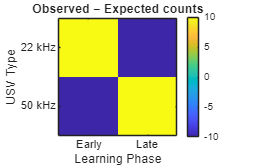

figure
imagesc(observed - expected)
colorbar
axis equal tight
title('Observed − Expected counts')
xlabel('Learning Phase')
ylabel('USV Type')
set(gca,'XTick',1:2,'XTickLabel',colLabels)
set(gca,'YTick',1:2,'YTickLabel',rowLabels)